**AWP ASSIGNMENT 2**

**NAME:NAKSHATHRA**

**160123735094**

 Q1. Broadside Array

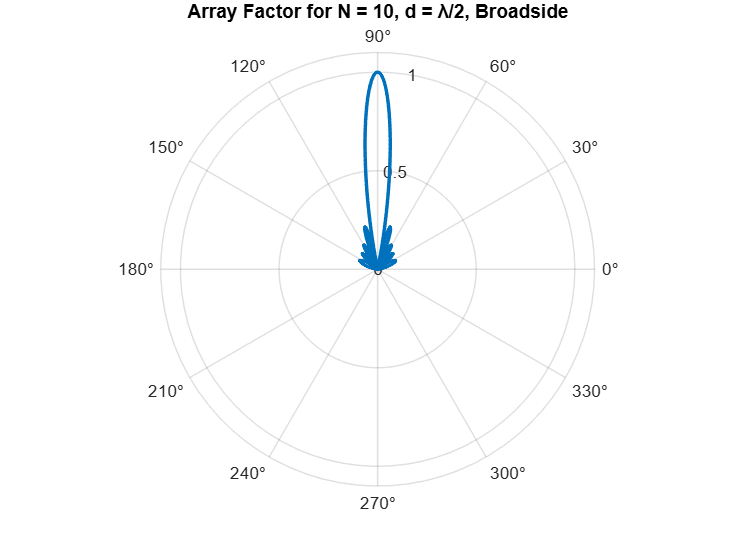

 N = 10;
 lambda = 1;       % Normalized wavelength
 k = 2 * pi / lambda;
 theta = linspace(0, pi, 1000);   % Angle in radians
 %% 1: d = λ/2
 d = lambda / 2;
 psi = k * d * cos(theta);  % Since beta = 0 for broadside
 AF = sin(N * psi / 2) ./ sin(psi / 2);
 AF = AF / max(abs(AF));    % Normalize
 % Plot AF
 figure;
 polarplot(theta, abs(AF), 'LineWidth', 2);
 title('Array Factor for N = 10, d = λ/2, Broadside');
 rlim([0 1.1]);

 % FNBW and Directivity
 FNBW_rad = 2 / (N * d)          % In radians

FNBW_rad = 0.4000

FNBW_deg = rad2deg(FNBW_rad)    

FNBW_deg = 22.9183

% In degrees
 D = 2 * N / FNBW_rad

D = 50

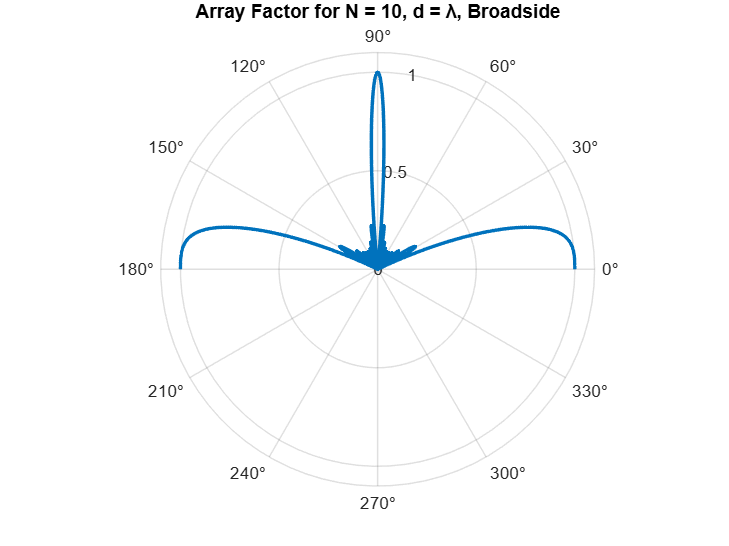


 %% 2: d = λ
 d = lambda;
 psi = k * d * cos(theta);  % Still broadside
 AF = sin(N * psi / 2) ./ sin(psi / 2);
 AF = AF / max(abs(AF));    
% Normalize
 % Plot AF
 figure;
 polarplot(theta, abs(AF), 'LineWidth', 2);
 title('Array Factor for N = 10, d = λ, Broadside');
 rlim([0 1.1]);

  % FNBW and Directivity
 FNBW_rad = 2 / (N * d)           

FNBW_rad = 0.2000

FNBW_deg = rad2deg(FNBW_rad)    

FNBW_deg = 11.4592

 D = 2 * N / FNBW_rad

D = 100

Q2.End-Fire Array 

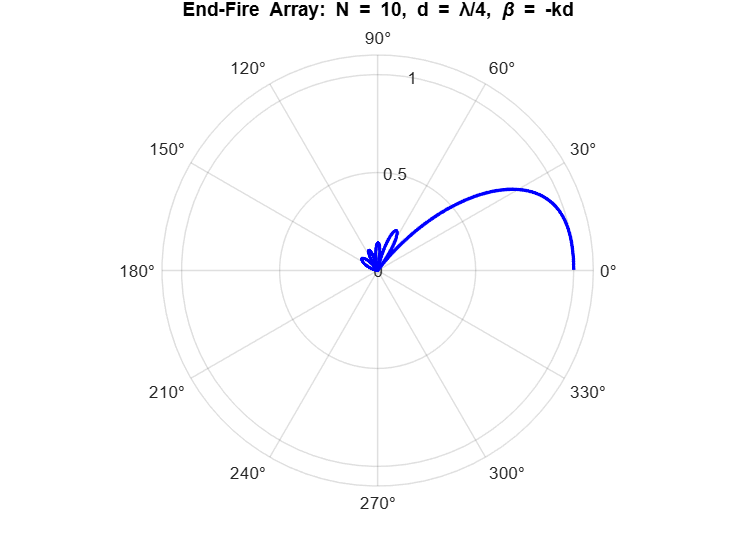

 N = 10;    
lambda = 1;              % Normalized wavelength
 k = 2 * pi / lambda;
 d = lambda / 4;          % Inter-element spacing
 theta = linspace(0, pi, 1000);   % Angle in radians
 %% 1: β = -kd (End-fire toward θ = 0°)
 beta = -k * d;
 psi = k * d * cos(theta) + beta;
 AF = sin(N * psi / 2) ./ sin(psi / 2);
 AF = AF / max(abs(AF));  % Normalize
 % Plot AF
 figure;
 polarplot(theta, abs(AF), 'b', 'LineWidth', 2);
 title('End-Fire Array: N = 10, d = λ/4, \beta = -kd', ...
    'Interpreter', 'tex');
 rlim([0 1.1]);

 % FNBW and Directivity
 FNBW_rad = 2 / (N * d)            

FNBW_rad = 0.8000

 FNBW_deg = rad2deg(FNBW_rad)    

FNBW_deg = 45.8366

 D = 2 * N / FNBW_rad

D = 25

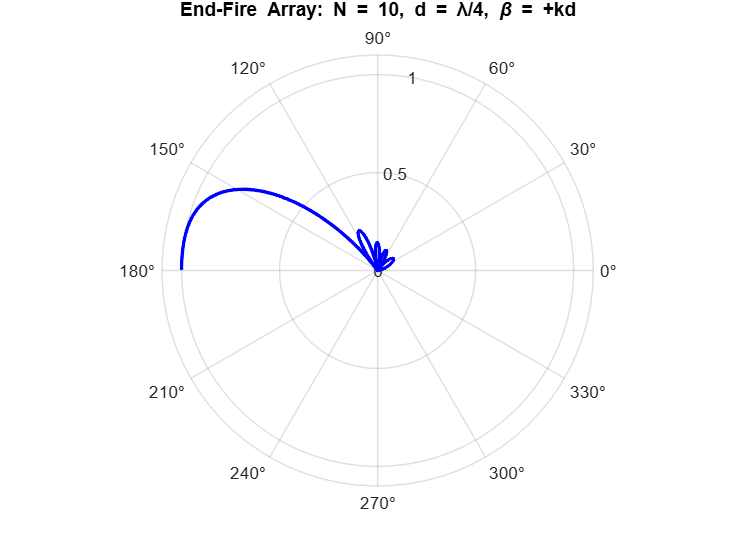

 %% 2: β = +kd (End-fire toward θ = 180°)
 beta = k * d;
 psi = k * d * cos(theta) + beta;
 AF = sin(N * psi / 2) ./ sin(psi / 2);
 AF = AF / max(abs(AF));  % Normalize
 % Plot AF
 figure;
 polarplot(theta, abs(AF), 'b', 'LineWidth', 2);
 title('End-Fire Array: N = 10, d = λ/4, \beta = +kd', ...
 'Interpreter', 'tex');
 rlim([0 1.1]);

  % FNBW and Directivity
 FNBW_rad = 2 / (N * d)          

FNBW_rad = 0.8000

 FNBW_deg = rad2deg(FNBW_rad)   

FNBW_deg = 45.8366

 D = 2 * N / FNBW_rad

D = 25

 Q3. Scanning Array at θ = 60° 

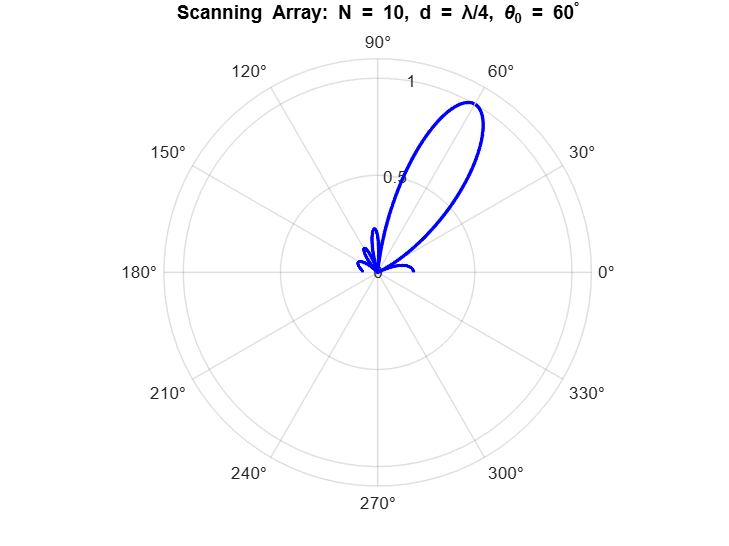

  N = 10;                   
lambda = 1;                   
k = 2 * pi / lambda;
 d = lambda / 4;               
% Normalized wavelength
 % Element spacing
 theta0_deg = 60;
 theta0 = deg2rad(theta0_deg);
 beta = -k * d * cos(theta0);  % Phase shift for scanning
 theta = linspace(0, pi, 1000);  % Angle range (0 to 180 deg)
 % Array Factor
 psi = k * d * cos(theta) + beta;
 AF = sin(N * psi / 2) ./ sin(psi / 2);
 AF = AF / max(abs(AF));      
% Normalize
 % Plot
 figure;
 polarplot(theta, abs(AF), 'b', 'LineWidth', 2);
 title(['Scanning Array: N = 10, d = λ/4, \theta_0 = ' num2str(theta0_deg) '^\circ'], ...
 'Interpreter', 'tex');
 rlim([0 1.1]);

  % FNBW and Directivity (approximate)
 FNBW_rad = 2 / (N * d)          

FNBW_rad = 0.8000

 FNBW_deg = rad2deg(FNBW_rad)     

FNBW_deg = 45.8366

 D = 2 * N / FNBW_rad

D = 25